% Q3
function analyze_graph()
    % analyze_graph(A, m, n, network_name)
    % A: Adjacency matrix
    % m: Number of edges
    % n: Number of nodes
    % network_name: Name of the network (string)
    clear values;
    clc;

    select_random_graphs;
    network_name = input('network name: ', 's');

    % Convert sparse adjacency matrix to full matrix for easier computation
    A_full = full(A);

    % Determine if the graph is directed
    if issymmetric(A_full)
        is_directed = 'No';
        G = graph(A_full);  % Create an undirected graph object
    else
        is_directed = 'Yes';
        G = digraph(A_full);  % Create a directed graph object
    end

    % Determine if the graph is weighted
    if all(A_full(A_full > 0) == 1)
        is_weighted = 'No';
    else
        is_weighted = 'Yes';
    end

    % Print the basic information
    fprintf('Graph Information:\n');
    fprintf('Number of nodes (n): %d\n', n);
    fprintf('Number of edges (m): %d\n', m);
    fprintf('Directed? %s\n', is_directed);
    fprintf('Weighted? %s\n', is_weighted);

    % Degree statistics using the adjacency matrix A
    degrees = sum(A_full, 2);  % Sum along rows to get degree of each node
    max_degree = max(degrees);
    min_degree = min(degrees);
    avg_degree = mean(degrees);

    fprintf('\nDegree Statistics:\n');
    fprintf('Minimum degree: %d\n', min_degree);
    fprintf('Maximum degree: %d\n', max_degree);
    fprintf('Average degree: %.2f\n', avg_degree);

    % Estimate the degree distribution type (rough heuristic)
    if max_degree > 10 * avg_degree
        degree_distribution_type = 'Power-Law';
    else
        degree_distribution_type = 'Unknown';
    end
    fprintf('Degree Distribution Type: %s\n', degree_distribution_type);

    % Compute Local Clustering Coefficient manually
    lcc = zeros(n, 1);  % Preallocate for speed
    for i = 1:n
        % Find the neighbors of node i by looking for non-zero entries in row i of the adjacency matrix
        nbrs = find(A_full(i, :));  % This returns the indices of neighbors
        k = length(nbrs);  % Degree of the node (number of neighbors)

        if k < 2
            lcc(i) = 0;  % If less than 2 neighbors, LCC is 0
        else
            % Adjacency matrix of the subgraph of neighbors
            subgraph_adj = A_full(nbrs, nbrs);  % Extract the adjacency matrix for neighbors
            num_links_between_neighbors = sum(subgraph_adj(:)) / 2;  % Number of edges in the neighborhood
            lcc(i) = 2 * num_links_between_neighbors / (k * (k - 1));  % LCC formula
        end
    end
    avg_lcc = mean(lcc);

    fprintf('\nClustering Coefficient:\n');
    fprintf('Average Local Clustering Coefficient (LCC): %.4f\n', avg_lcc);

    % Check if the graph is connected (for undirected graphs)
    if strcmp(is_directed, 'No')
        % Get the connected components
        components = conncomp(G);
        if max(components) == 1  % If there's only one component, the graph is connected
            % Compute the shortest path distance between all pairs of nodes
            shortest_distances = distances(G);  % Renamed from 'distances' to 'shortest_distances'

            % The diameter is the maximum distance between nodes that are connected
            diameter_value = max(shortest_distances(~isinf(shortest_distances)));
            fprintf('Diameter: %.2f\n', diameter_value);
        else
            fprintf('The graph is not connected. Diameter cannot be computed.\n');
        end
    end

    % Set the number of bins for the histogram
    nbins = 50;

    % Plot Degree Distribution
    figID = 1;  % Use figure ID 1 for degree distribution
    degree_distribution_name = [network_name, ' Degree Distribution'];
    plot_distribution(degrees, degree_distribution_name, nbins, figID);

    % Plot Local Clustering Coefficient (LCC) Distribution
    figID = 2;  % Use figure ID 2 for LCC distribution
    lcc_distribution_name = [network_name, ' LCC Distribution'];
    plot_distribution(lcc, lcc_distribution_name, nbins, figID);

    % Plot the graph structure
    figure(3);
    plot(G);
    title([network_name, ' Graph Structure']);
    xlabel('X');
    ylabel('Y');
end


   1 : er_n3000_p0.3.mat
   2 : ba_n3000_k20.mat
   3 : ws_n3000_b10_r0.mat
   4 : ws_n3000_b10_r0.01.mat
   5 : rg_n3000_d2_r0.0469_s0.mat
   Graph er_n3000_p0.3 : [n,m] = [3000, 1348835] 

Graph Information:
Number of nodes (n): 3000
Number of edges (m): 1348835
Directed? No
Weighted? No

Degree Statistics:
Minimum degree: 820
Maximum degree: 994
Average degree: 899.22
Degree Distribution Type: Unknown

Clustering Coefficient:
Average Local Clustering Coefficient (LCC): 0.2999
Diameter: 2.00


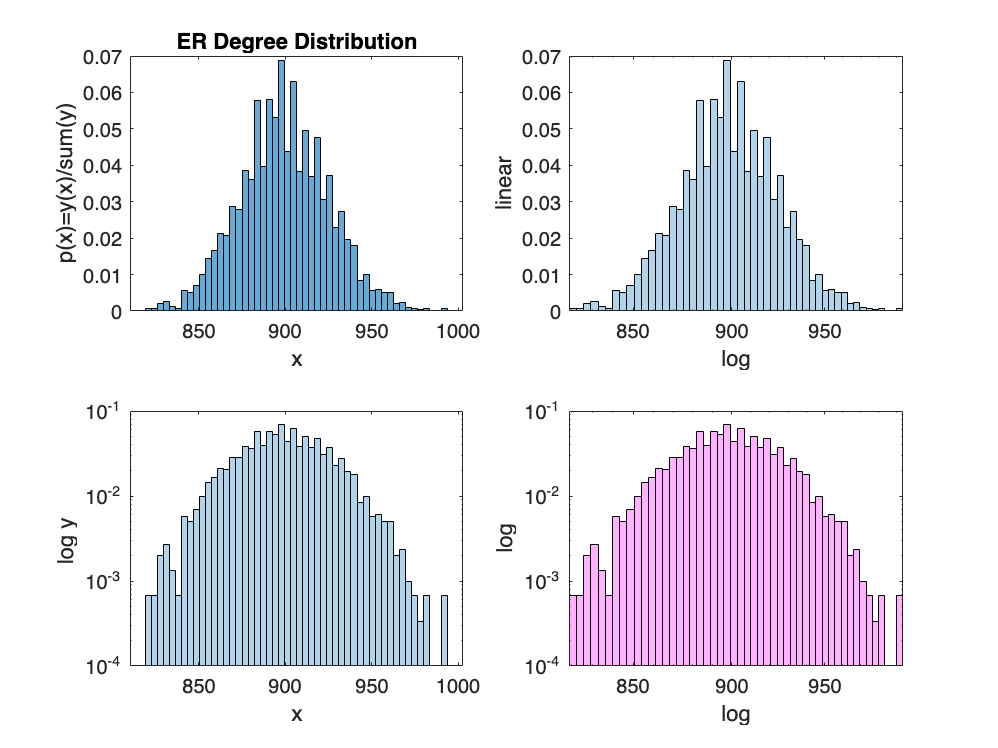

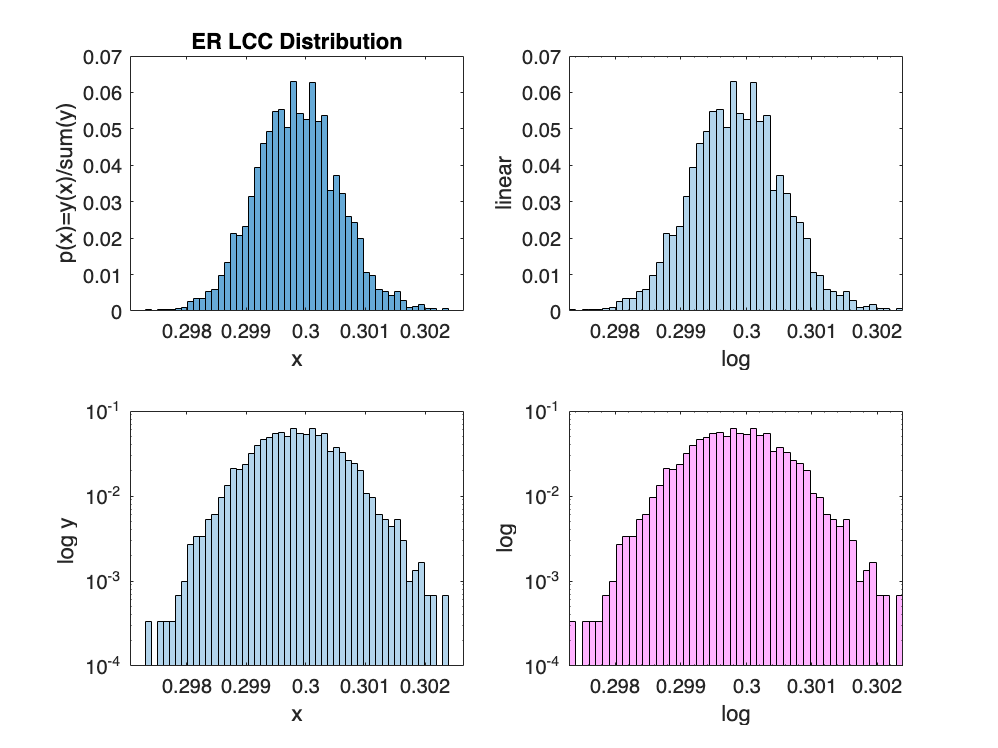

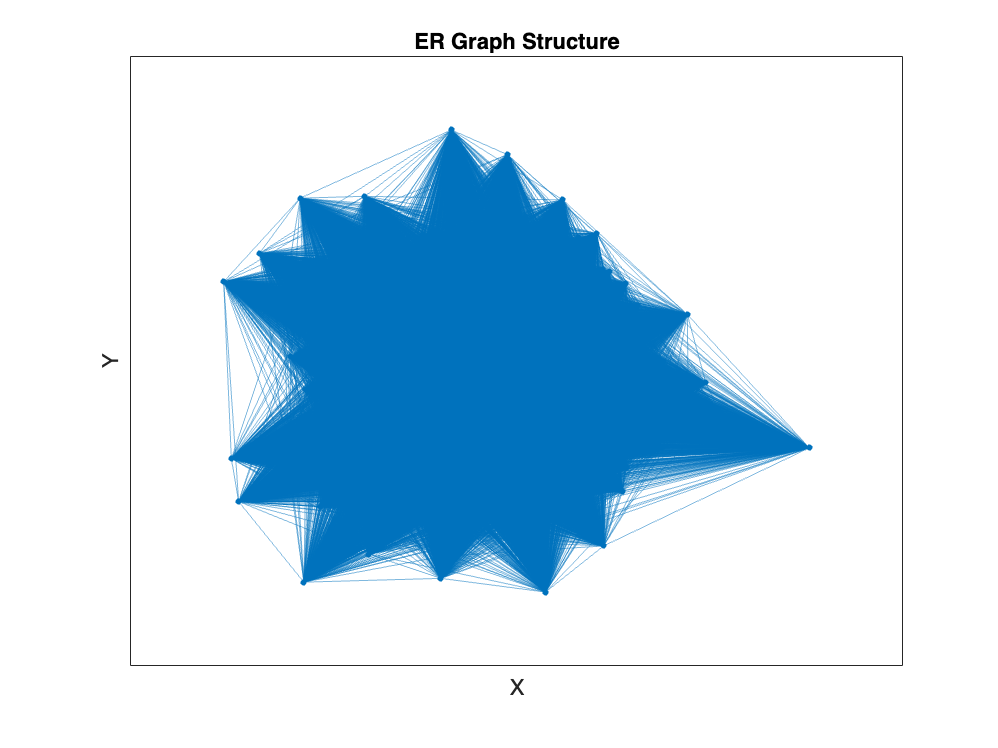

% Call the function
analyze_graph();


   1 : er_n3000_p0.3.mat
   2 : ba_n3000_k20.mat
   3 : ws_n3000_b10_r0.mat
   4 : ws_n3000_b10_r0.01.mat
   5 : rg_n3000_d2_r0.0469_s0.mat
   Graph ba_n3000_k20 : [n,m] = [3000, 59790] 

Graph Information:
Number of nodes (n): 3000
Number of edges (m): 59790
Directed? No
Weighted? No

Degree Statistics:
Minimum degree: 20
Maximum degree: 358
Average degree: 39.86
Degree Distribution Type: Unknown

Clustering Coefficient:
Average Local Clustering Coefficient (LCC): 0.0468
Diameter: 4.00


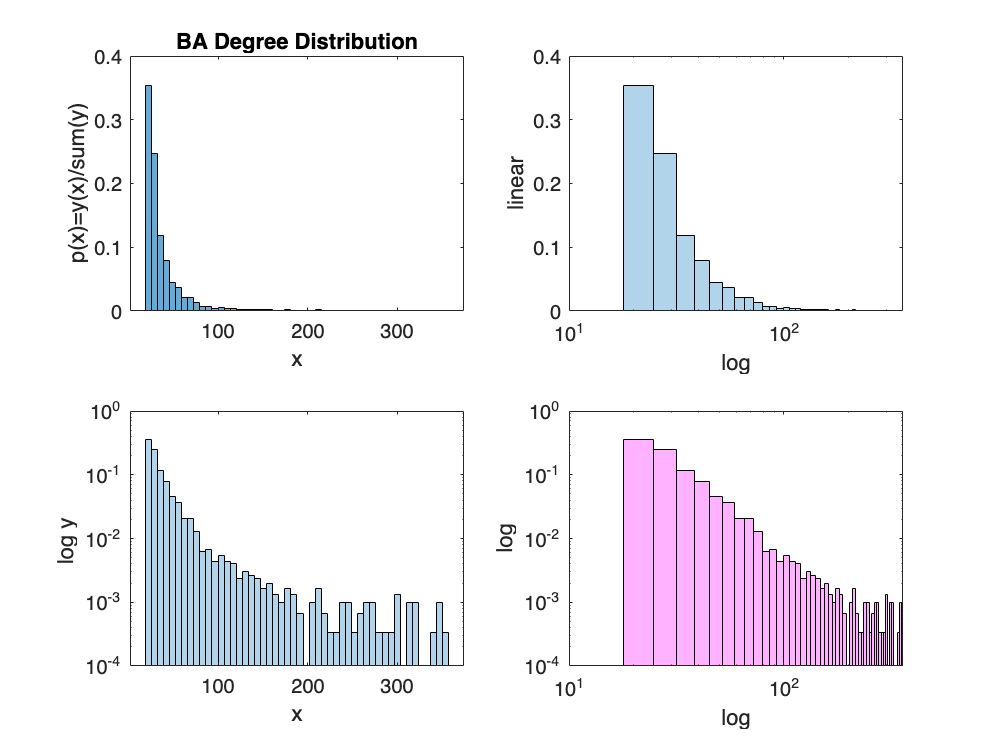

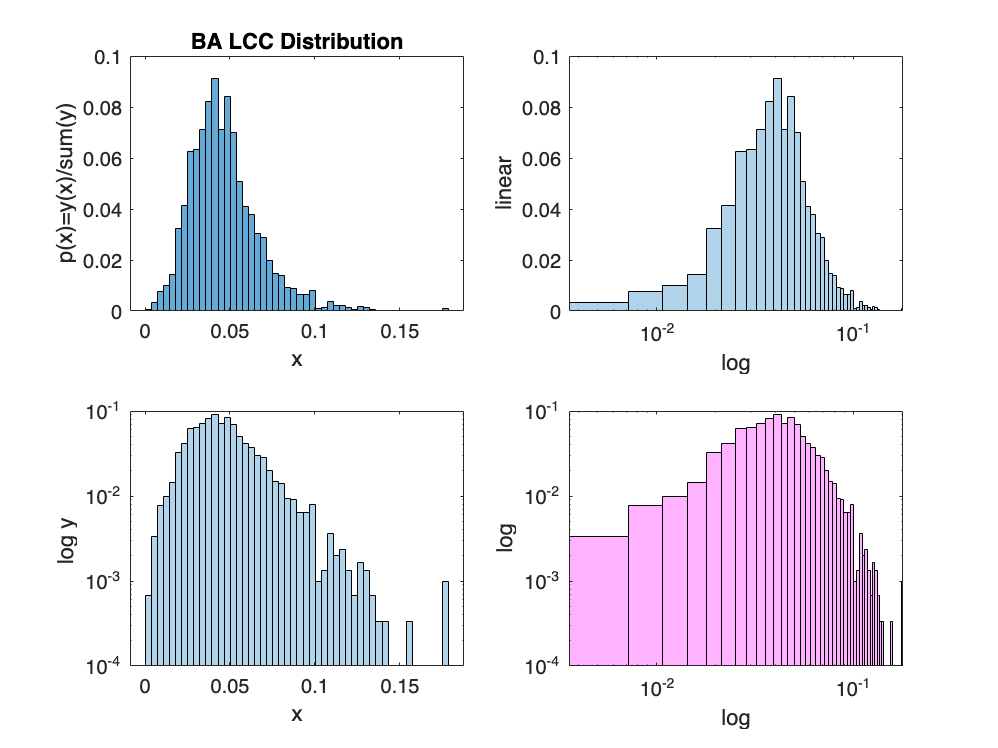

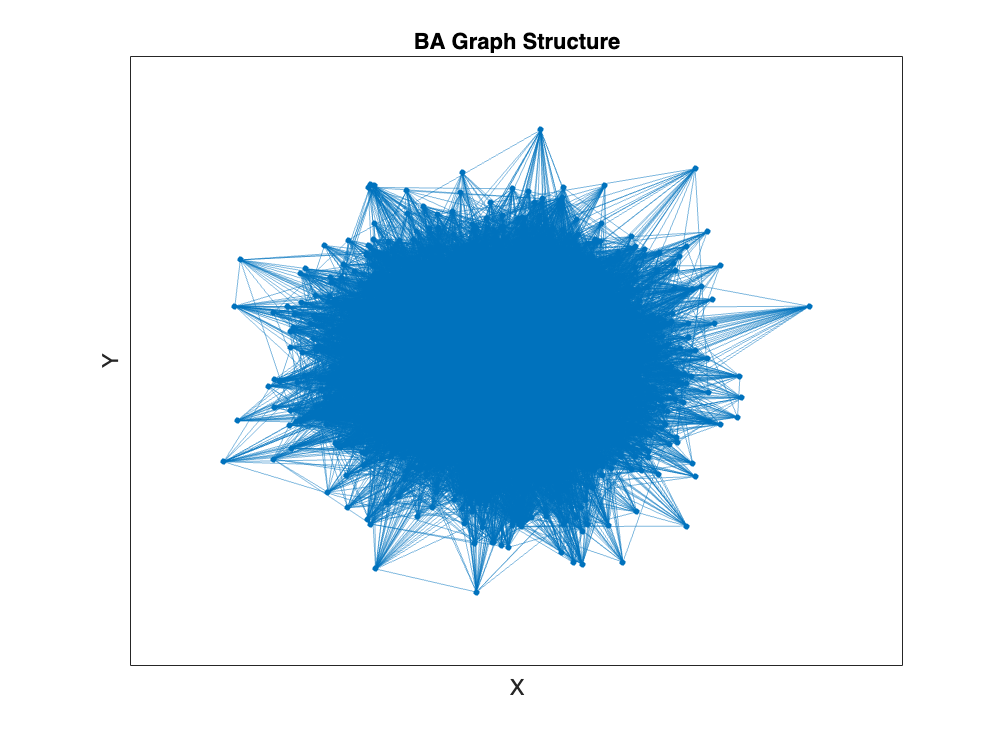

% Call the function
analyze_graph();


   1 : er_n3000_p0.3.mat
   2 : ba_n3000_k20.mat
   3 : ws_n3000_b10_r0.mat
   4 : ws_n3000_b10_r0.01.mat
   5 : rg_n3000_d2_r0.0469_s0.mat
   Graph ws_n3000_b10_r0 : [n,m] = [3000, 30000] 

Graph Information:
Number of nodes (n): 3000
Number of edges (m): 30000
Directed? No
Weighted? No

Degree Statistics:
Minimum degree: 20
Maximum degree: 20
Average degree: 20.00
Degree Distribution Type: Unknown

Clustering Coefficient:
Average Local Clustering Coefficient (LCC): 0.7105
Diameter: 150.00


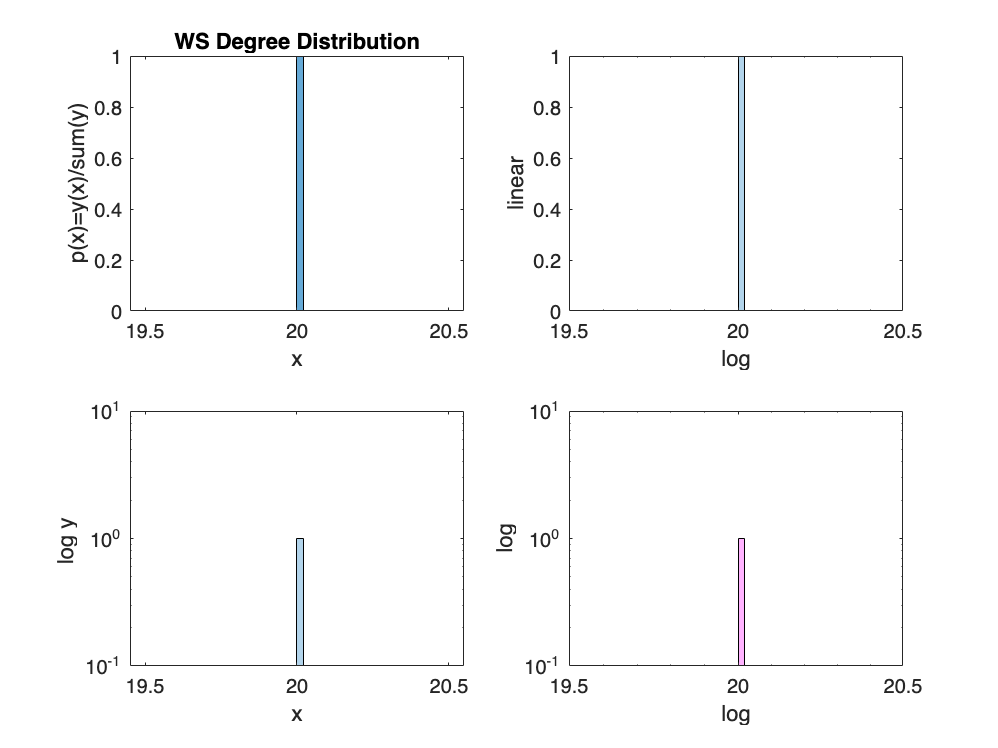

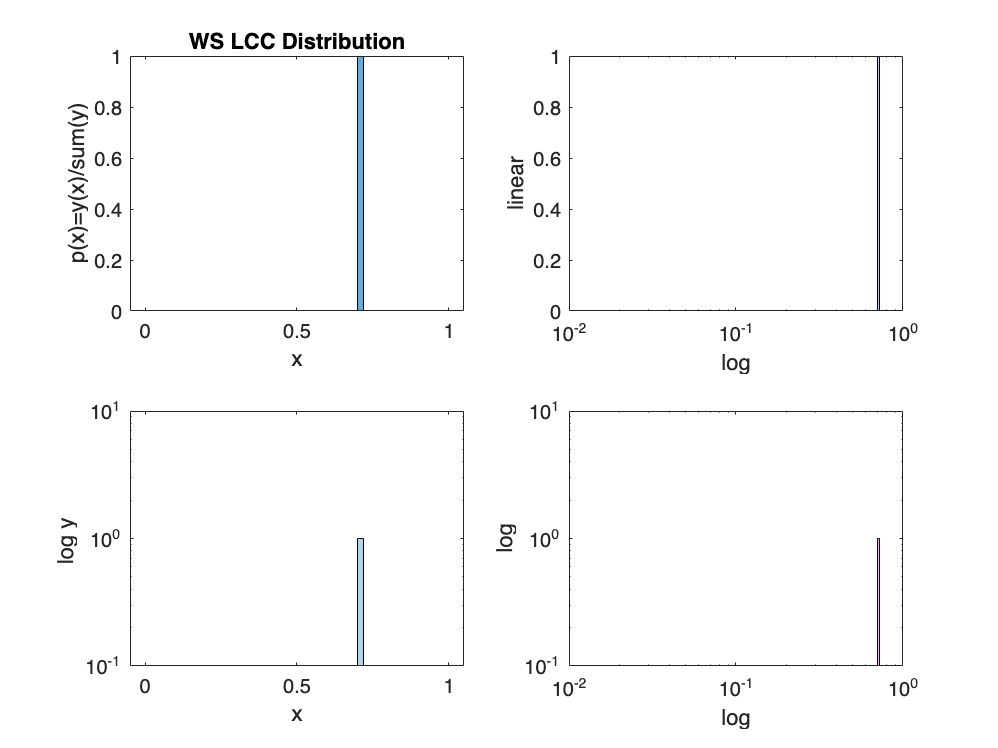

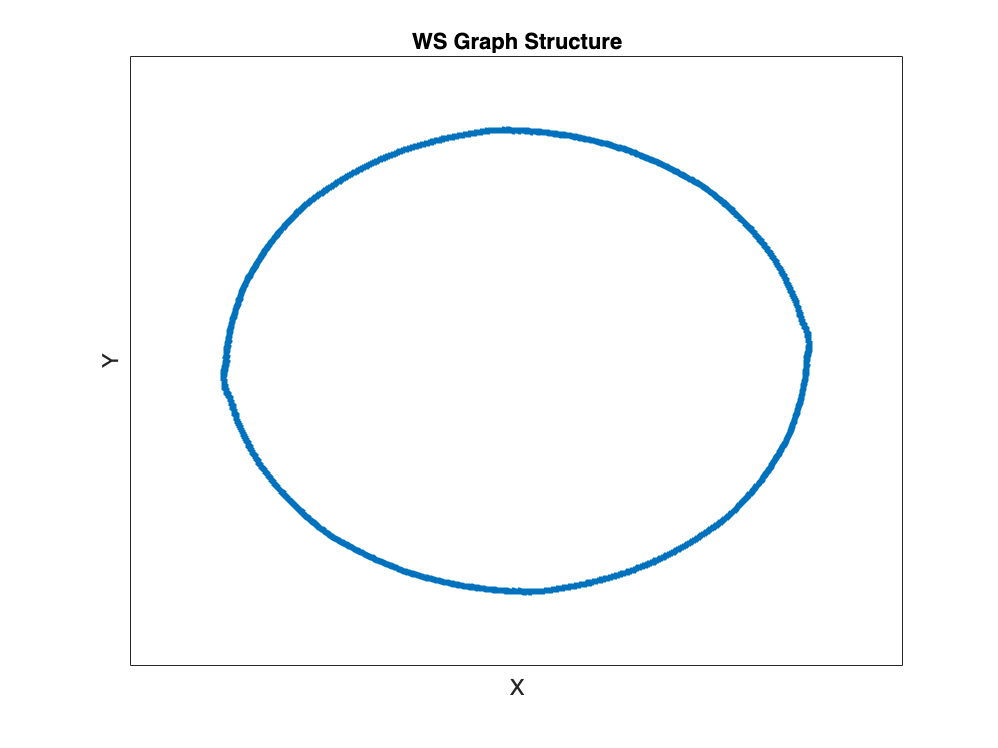

% Call the function
analyze_graph();


   1 : er_n3000_p0.3.mat
   2 : ba_n3000_k20.mat
   3 : ws_n3000_b10_r0.mat
   4 : ws_n3000_b10_r0.01.mat
   5 : rg_n3000_d2_r0.0469_s0.mat
   Graph ws_n3000_b10_r0.01 : [n,m] = [3000, 30000] 

Graph Information:
Number of nodes (n): 3000
Number of edges (m): 30000
Directed? No
Weighted? No

Degree Statistics:
Minimum degree: 17
Maximum degree: 22
Average degree: 20.00
Degree Distribution Type: Unknown

Clustering Coefficient:
Average Local Clustering Coefficient (LCC): 0.6882
Diameter: 10.00


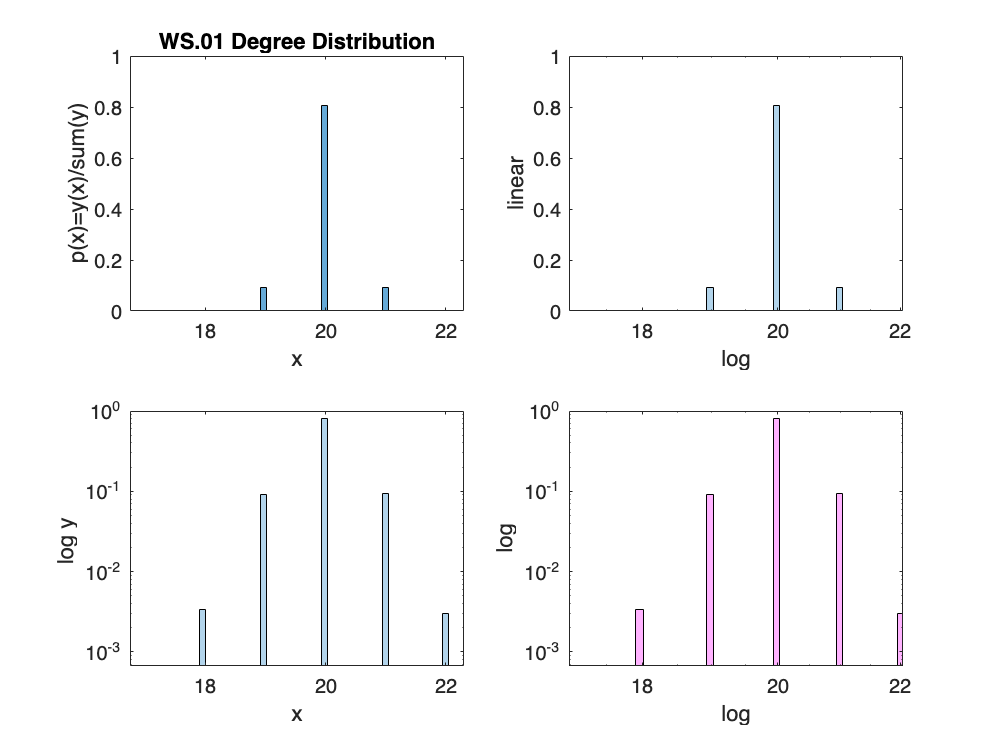

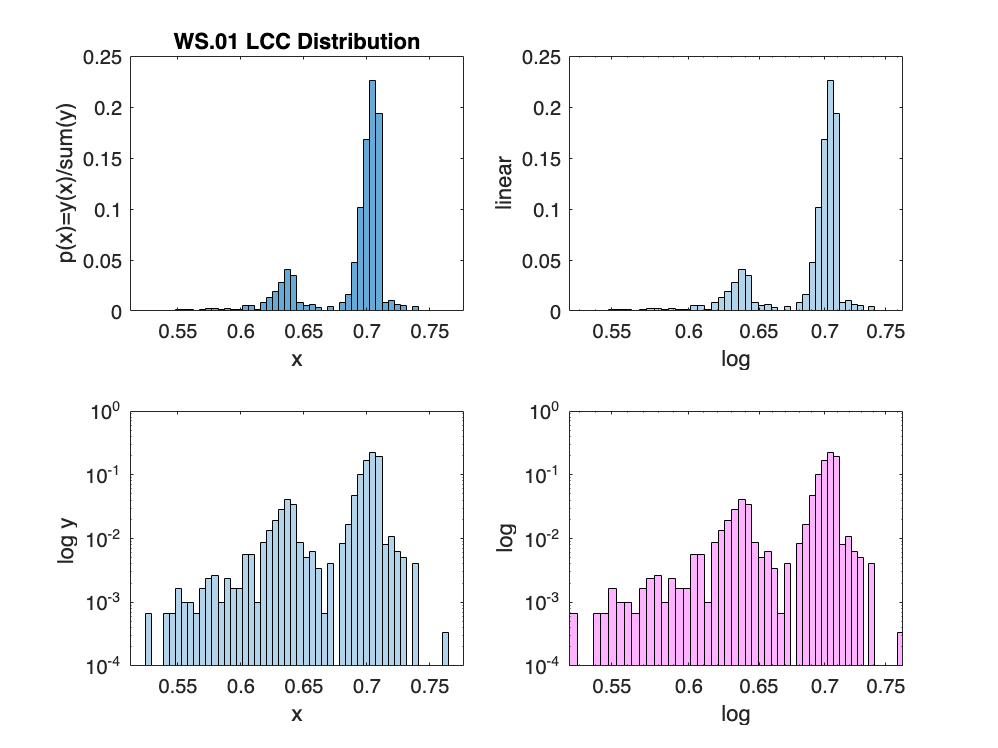

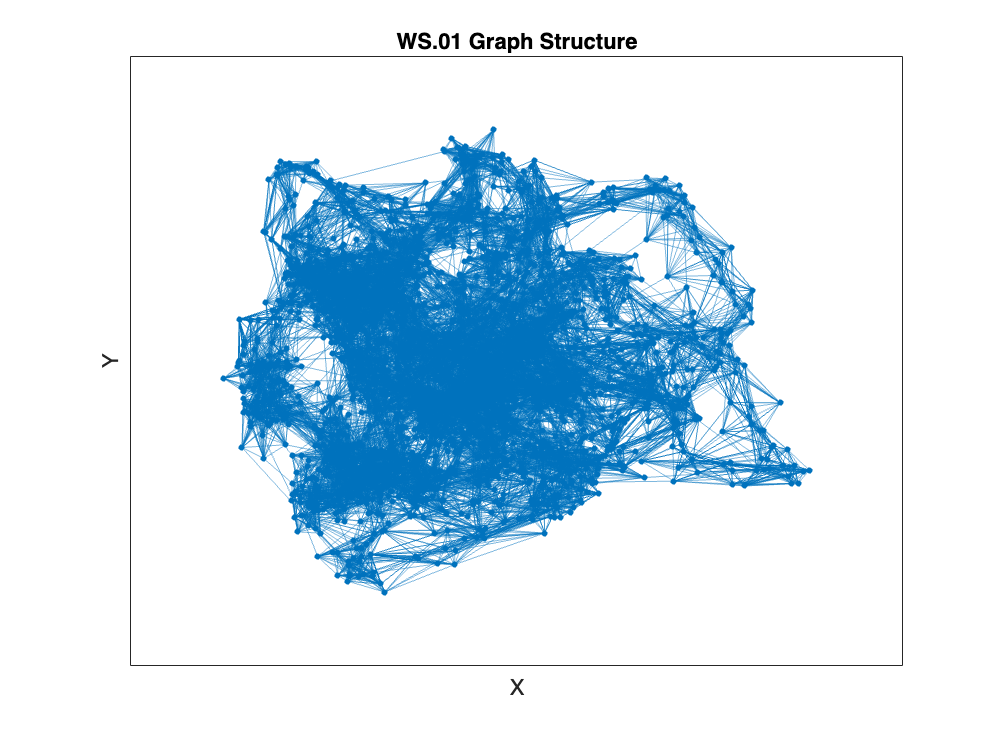

% Call the function
analyze_graph();


   1 : er_n3000_p0.3.mat
   2 : ba_n3000_k20.mat
   3 : ws_n3000_b10_r0.mat
   4 : ws_n3000_b10_r0.01.mat
   5 : rg_n3000_d2_r0.0469_s0.mat
   Graph rg_n3000_d2_r0.0469_s0 : [n,m] = [3000, 30013] 

Graph Information:
Number of nodes (n): 3000
Number of edges (m): 30013
Directed? No
Weighted? No

Degree Statistics:
Minimum degree: 3
Maximum degree: 40
Average degree: 20.01
Degree Distribution Type: Unknown

Clustering Coefficient:
Average Local Clustering Coefficient (LCC): 0.6032
Diameter: 35.00


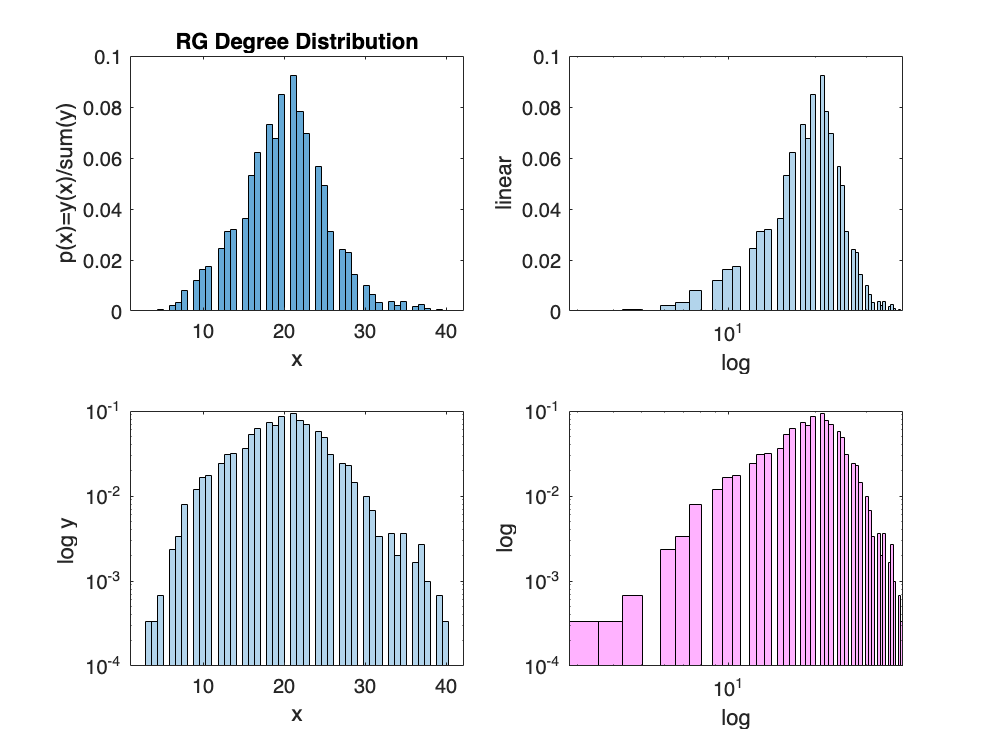

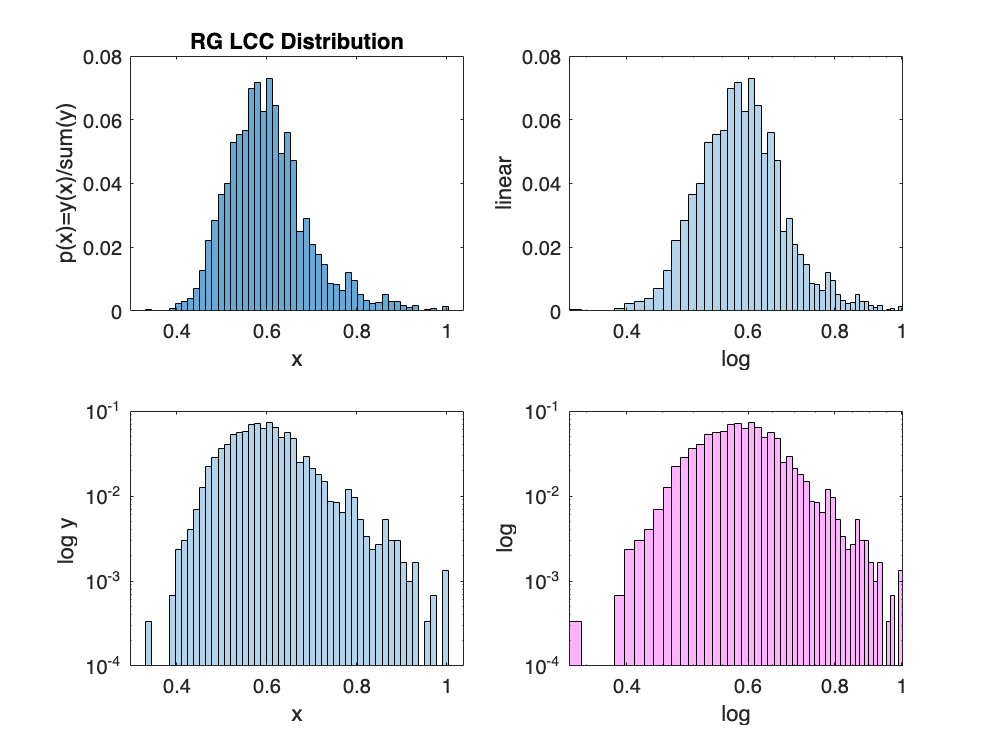

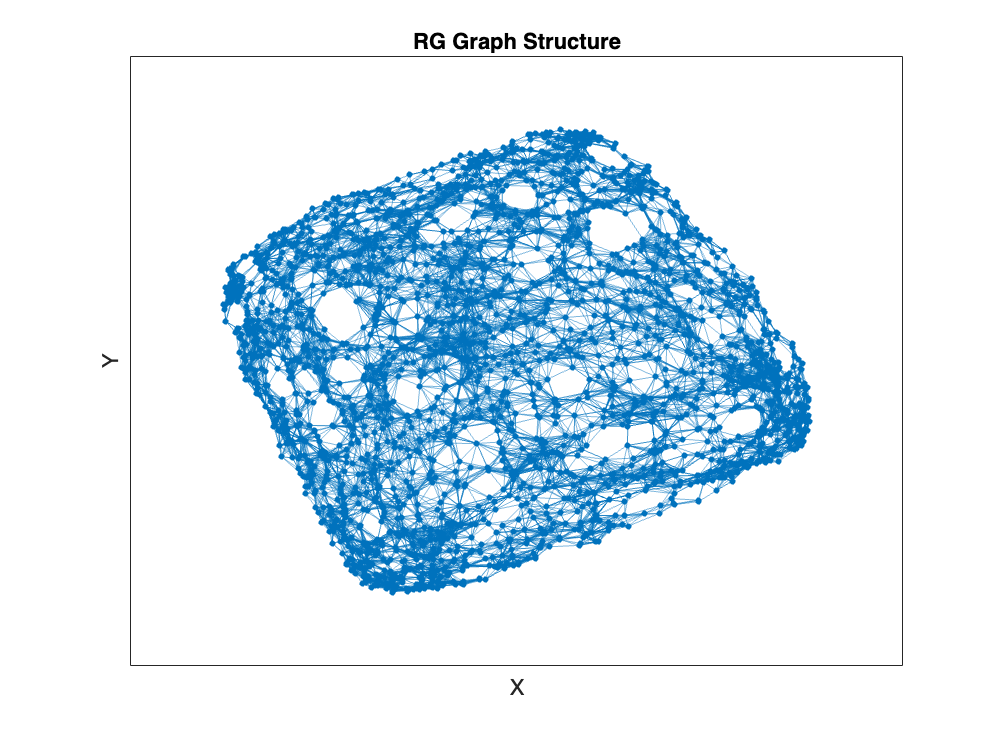

% Call the function
analyze_graph();


   1 : er_n3000_p0.3.mat
   2 : ba_n3000_k20.mat
   3 : ws_n3000_b10_r0.mat
   4 : ws_n3000_b10_r0.01.mat
   5 : rg_n3000_d2_r0.0469_s0.mat
   Graph er_n3000_p0.3 : [n,m] = [3000, 1348835] 

Graph Information:
Number of nodes (n): 3000
Number of edges (m): 1348835
Directed? No
Weighted? No

Degree Statistics:
Minimum degree: 820
Maximum degree: 994
Average degree: 899.22
Degree Distribution Type: Unknown

Clustering Coefficient:
Average Local Clustering Coefficient (LCC): 0.2999
Diameter: 2.00


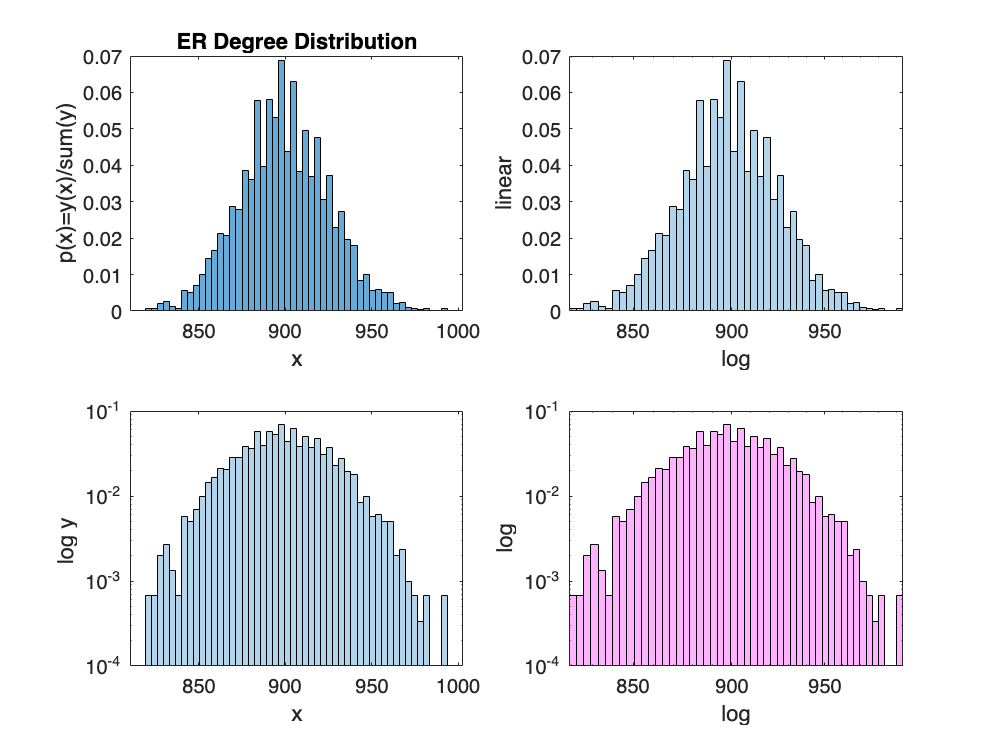

function analyze_graph1()
    % analyze_graph(A, m, n, network_name)
    % A: Adjacency matrix
    % m: Number of edges
    % n: Number of nodes
    % network_name: Name of the network (string)
    clear values;
    clc;

    select_topological_graphs;
    network_name = input('network name: ', 's')

    % Convert sparse adjacency matrix to full matrix for easier computation
    A_full = full(A);

    % Determine if the graph is directed
    if issymmetric(A_full)
        is_directed = 'No';
        G = graph(A_full);  % Create an undirected graph object
    else
        is_directed = 'Yes';
        G = digraph(A_full);  % Create a directed graph object
    end

    % Determine if the graph is weighted
    if all(A_full(A_full > 0) == 1)
        is_weighted = 'No';
    else
        is_weighted = 'Yes';
    end

    % Print the basic information
    fprintf('Graph Information:\n');
    fprintf('Number of nodes (n): %d\n', n);
    fprintf('Number of edges (m): %d\n', m);
    fprintf('Directed? %s\n', is_directed);
    fprintf('Weighted? %s\n', is_weighted);

    % Degree statistics using the adjacency matrix A
    degrees = sum(A_full, 2);  % Sum along rows to get degree of each node
    max_degree = max(degrees);
    min_degree = min(degrees);
    avg_degree = mean(degrees);

    fprintf('\nDegree Statistics:\n');
    fprintf('Minimum degree: %d\n', min_degree);
    fprintf('Maximum degree: %d\n', max_degree);
    fprintf('Average degree: %.2f\n', avg_degree);

    % Estimate the degree distribution type (rough heuristic)
    if max_degree > 10 * avg_degree
        degree_distribution_type = 'Power-Law';
    else
        degree_distribution_type = 'Unknown';
    end
    fprintf('Degree Distribution Type: %s\n', degree_distribution_type);

    % Compute Local Clustering Coefficient manually
    lcc = zeros(n, 1);  % Preallocate for speed
    for i = 1:n
        % Find the neighbors of node i by looking for non-zero entries in row i of the adjacency matrix
        nbrs = find(A_full(i, :));  % This returns the indices of neighbors
        k = length(nbrs);  % Degree of the node (number of neighbors)

        if k < 2
            lcc(i) = 0;  % If less than 2 neighbors, LCC is 0
        else
            % Adjacency matrix of the subgraph of neighbors
            subgraph_adj = A_full(nbrs, nbrs);  % Extract the adjacency matrix for neighbors
            num_links_between_neighbors = sum(subgraph_adj(:)) / 2;  % Number of edges in the neighborhood
            lcc(i) = 2 * num_links_between_neighbors / (k * (k - 1));  % LCC formula
        end
    end
    avg_lcc = mean(lcc);

    fprintf('\nClustering Coefficient:\n');
    fprintf('Average Local Clustering Coefficient (LCC): %.4f\n', avg_lcc);

    % Check if the graph is connected (for undirected graphs)
    if strcmp(is_directed, 'No')
        % Get the connected components
        components = conncomp(G);
        if max(components) == 1  % If there's only one component, the graph is connected
            % Compute the shortest path distance between all pairs of nodes
            shortest_distances = distances(G);  % Renamed from 'distances' to 'shortest_distances'

            % The diameter is the maximum distance between nodes that are connected
            diameter_value = max(shortest_distances(~isinf(shortest_distances)));
            fprintf('Diameter: %.2f\n', diameter_value);
        else
            fprintf('The graph is not connected. Diameter cannot be computed.\n');
        end
    end

    % Set the number of bins for the histogram
    nbins = 50;

    % Plot Degree Distribution
    figID = 1;  % Use figure ID 1 for degree distribution
    degree_distribution_name = [network_name, ' Degree Distribution'];
    plot_distribution(degrees, degree_distribution_name, nbins, figID);

    % Plot Local Clustering Coefficient (LCC) Distribution
    figID = 2;  % Use figure ID 2 for LCC distribution
    lcc_distribution_name = [network_name, ' LCC Distribution'];
    plot_distribution(lcc, lcc_distribution_name, nbins, figID);

    % Plot the graph structure
    figure(3);
    plot(G);
    title([network_name, ' Graph Structure']);
    xlabel('X');
    ylabel('Y');
end

% Call the function
analyze_graph();


   demo_Laplacian_spectra begin 




   1 : binomialtree
   2 : buckyball
   3 : clique
   4 : grid
   5 : torus
   6 : grapheneSheet
   7 : hypercube
   8 : mycielski
   9 : rings
   10 : rok
   11 : wheel

   Graph buckyball:  [#nodes, #edges] = [60, 90] 



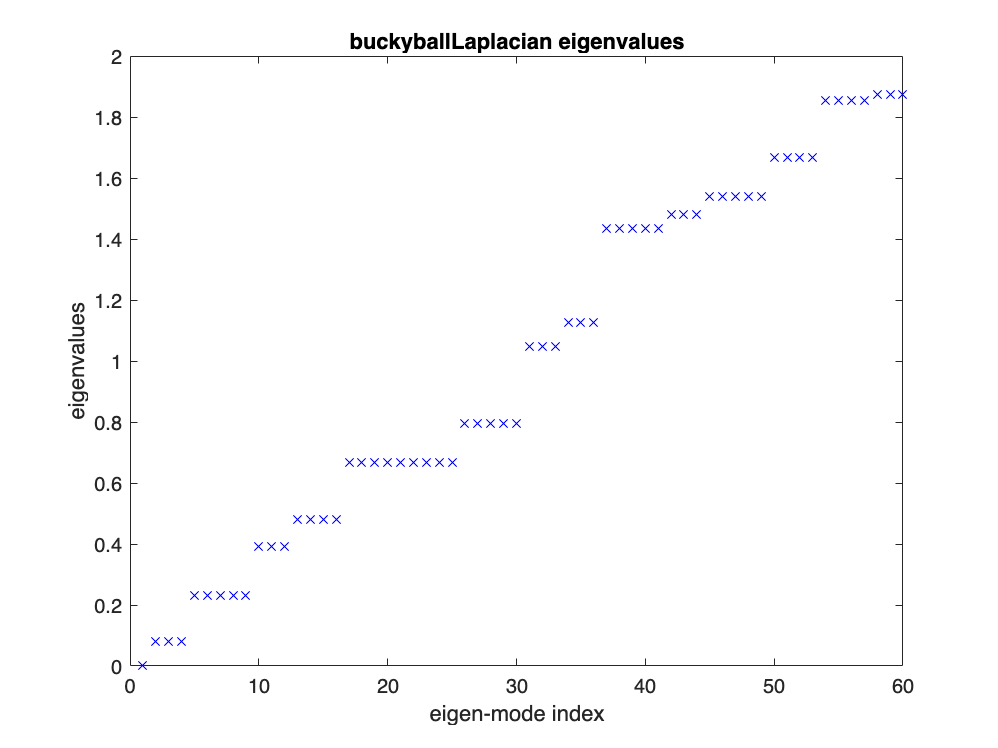

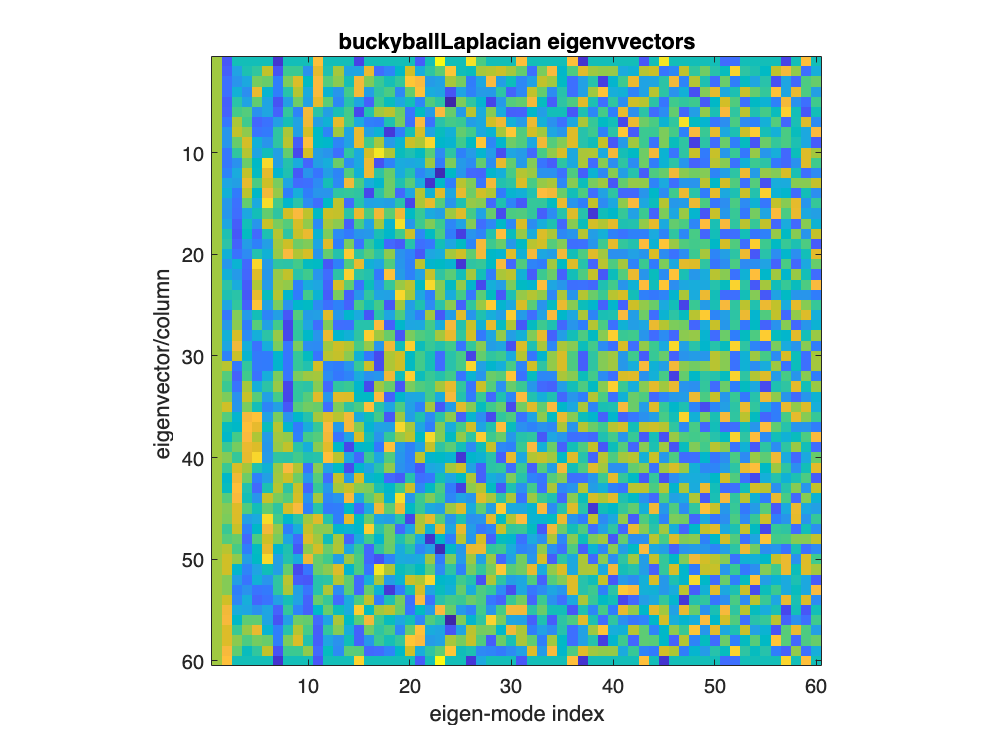


   2D vertex embeddng with low-energy modes ...

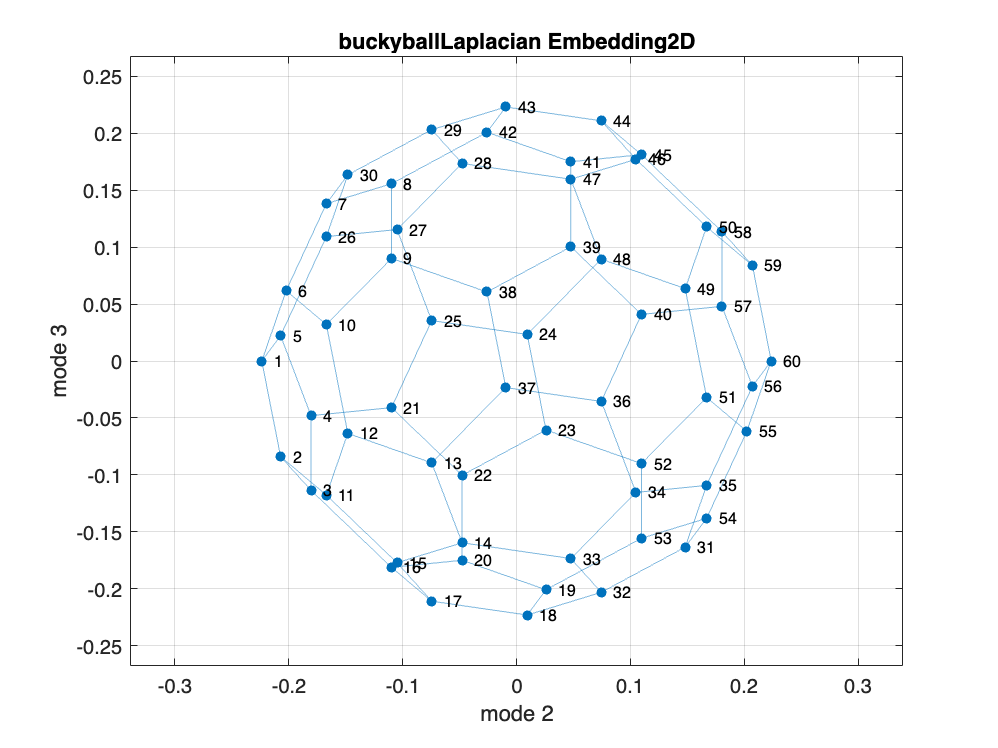


   3D vertex embeddng with low-energy modes ...

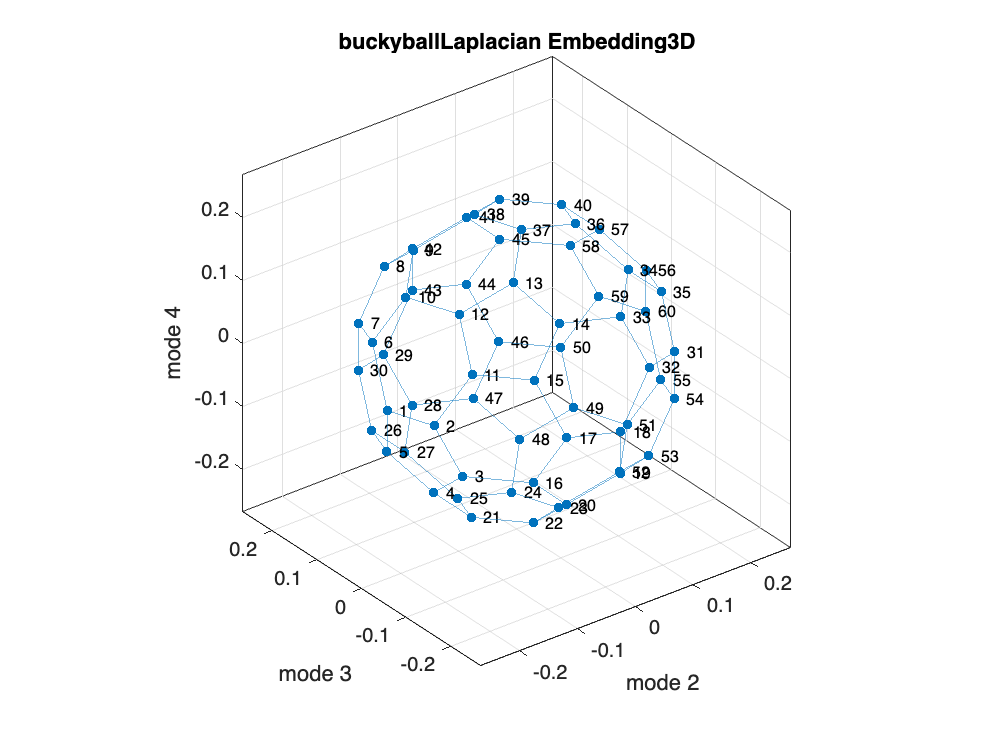


   3D vertex embeddng with high-energy modes ...

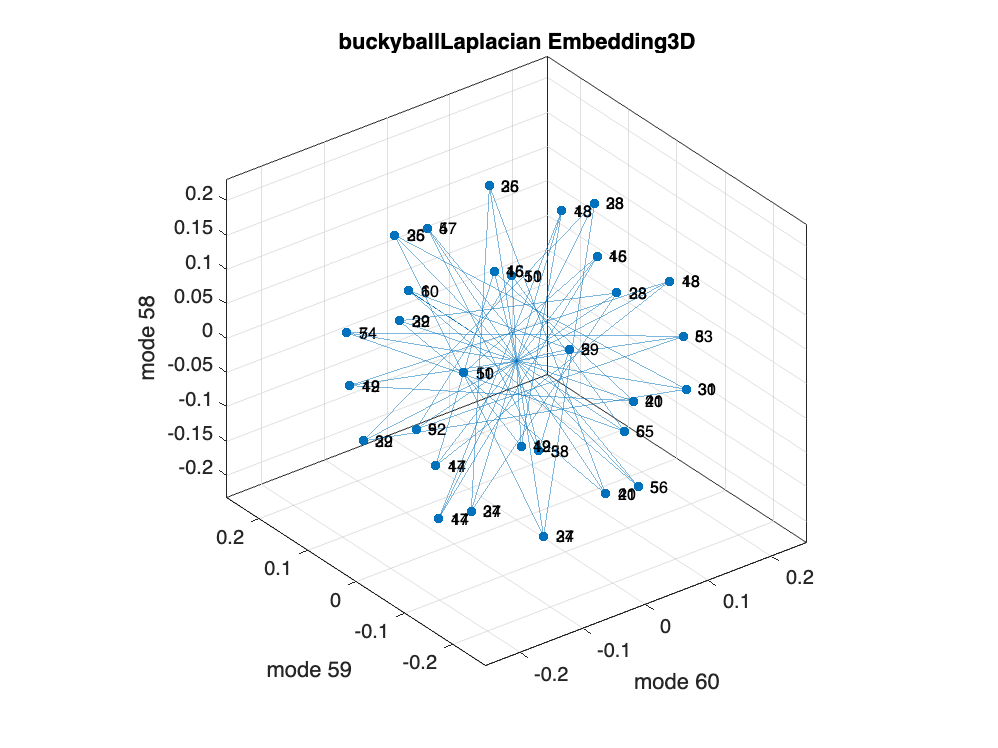



   demo_Laplacian_spectra end 



% Q5
demo_Laplacian_spectra;


fiedler_vector = Leig.V(:, 2);  % Second smallest eigenvector

% Partition the graph using the Fiedler vector
partition1 = find(fiedler_vector > 0);   % Positive values in Fiedler vector
partition2 = find(fiedler_vector <= 0);  % Non-positive values in Fiedler vector


% Create graph object
G = graph(A);

disp('Plotting...');

Plotting...


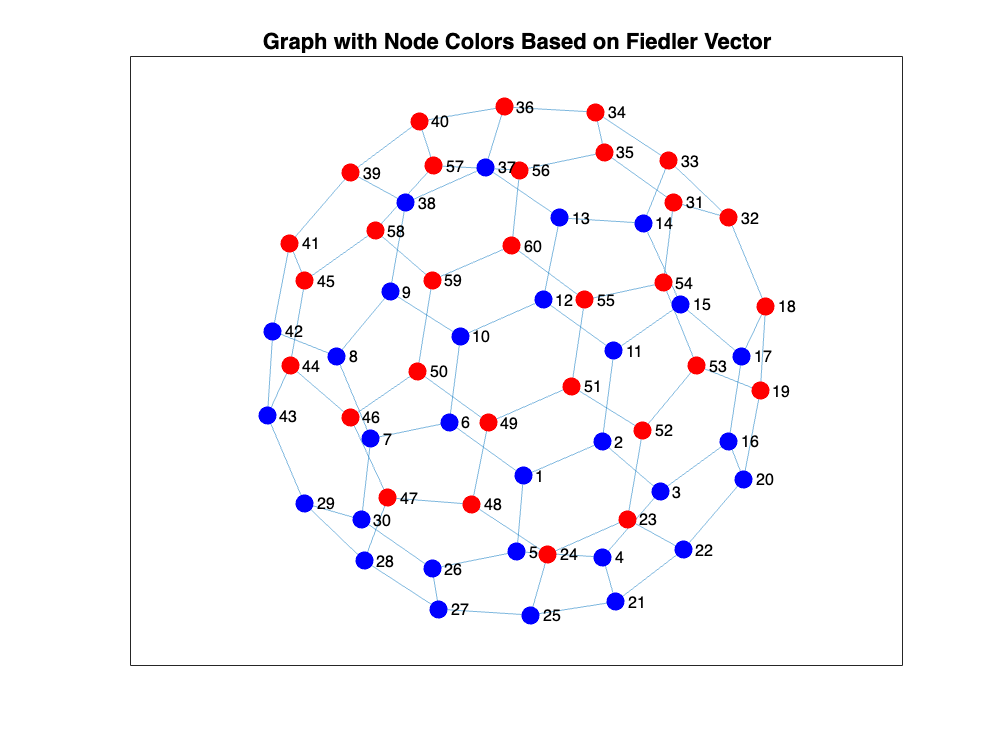

% Plot the graph without using NodeCData
figure
h = plot(G, 'MarkerSize', 8);
title('Graph Cut Using Fiedler Vector');
axis equal; box on;

% Highlight partition 1 (nodes with positive Fiedler vector values) in red
highlight(h, partition1, 'NodeColor', 'r');

% Highlight partition 2 (nodes with non-positive Fiedler vector values) in blue
highlight(h, partition2, 'NodeColor', 'b');
title('Graph with Node Colors Based on Fiedler Vector');
axis equal; box on;


   demo_Laplacian_spectra begin 




   1 : binomialtree
   2 : buckyball
   3 : clique
   4 : grid
   5 : torus
   6 : grapheneSheet
   7 : hypercube
   8 : mycielski
   9 : rings
   10 : rok
   11 : wheel

   Graph rings:  [#nodes, #edges] = [60, 120] 



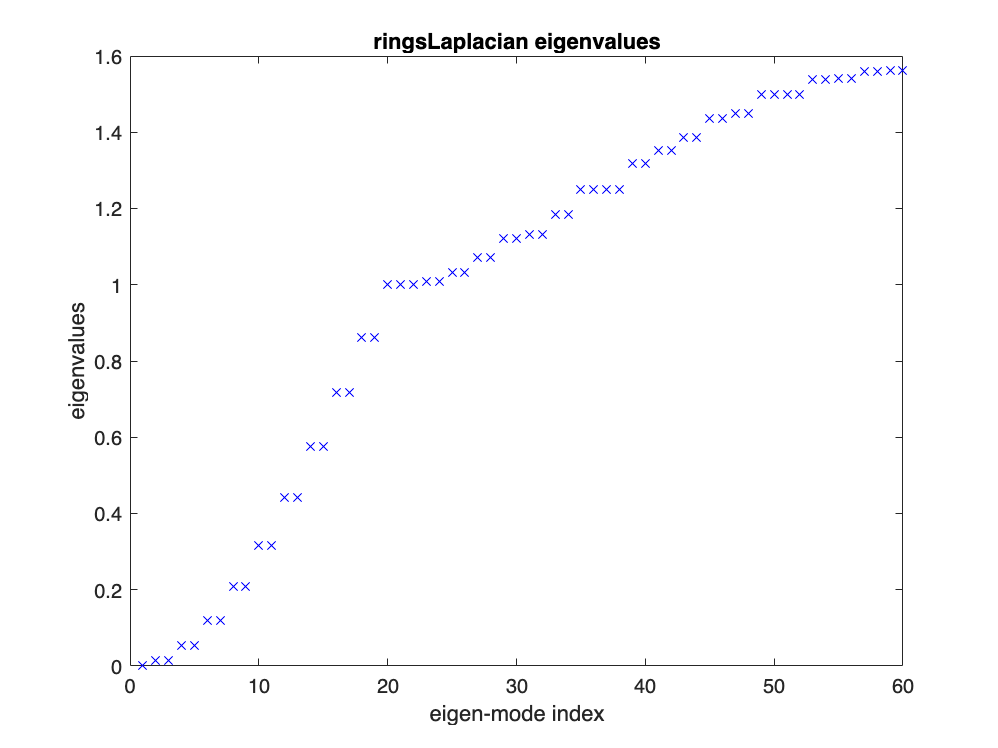

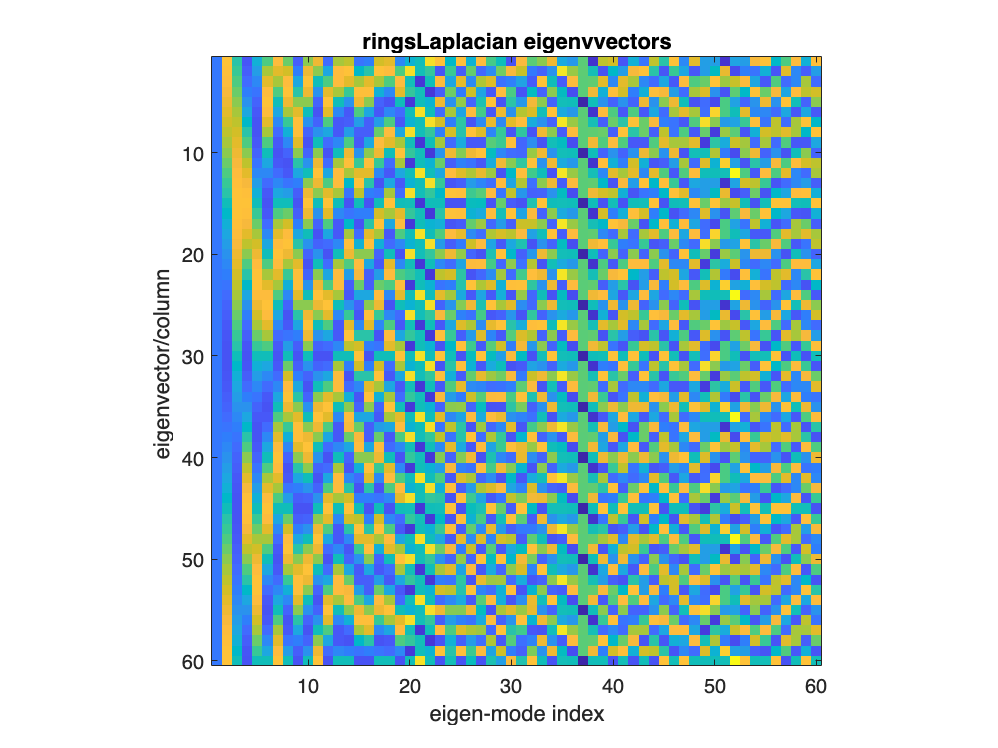


   2D vertex embeddng with low-energy modes ...

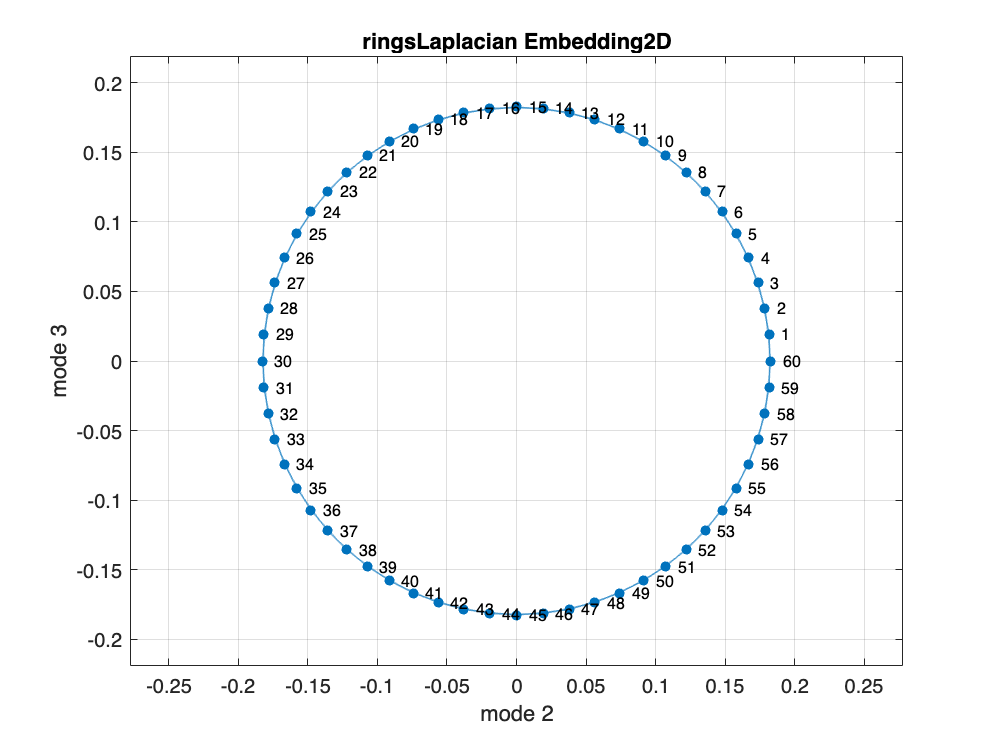


   3D vertex embeddng with low-energy modes ...

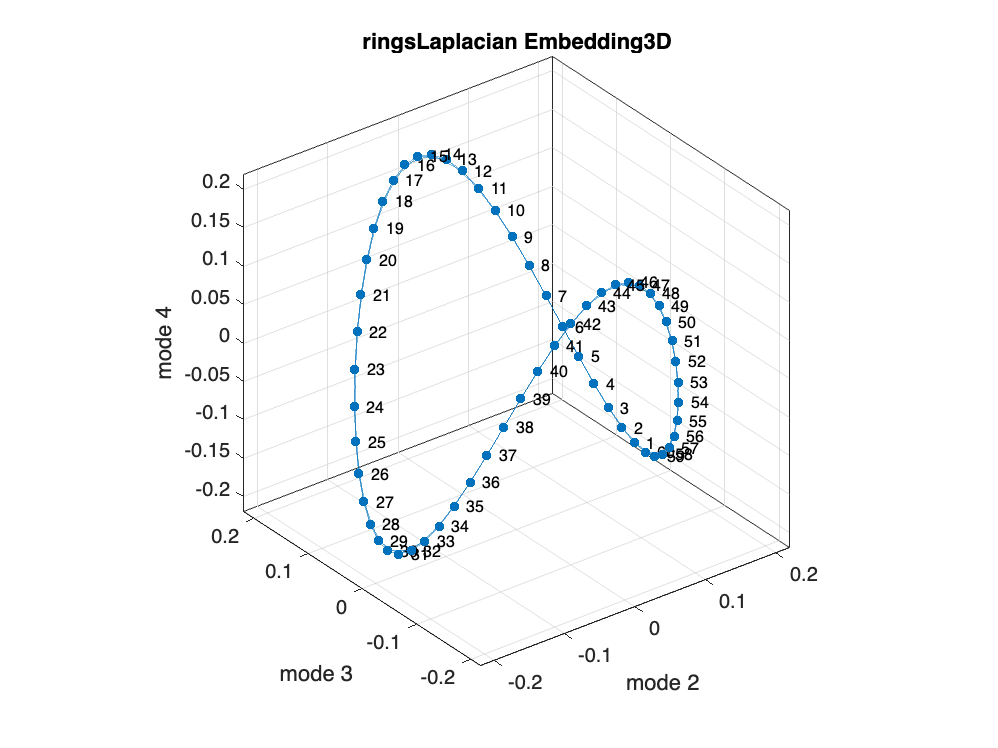


   3D vertex embeddng with high-energy modes ...

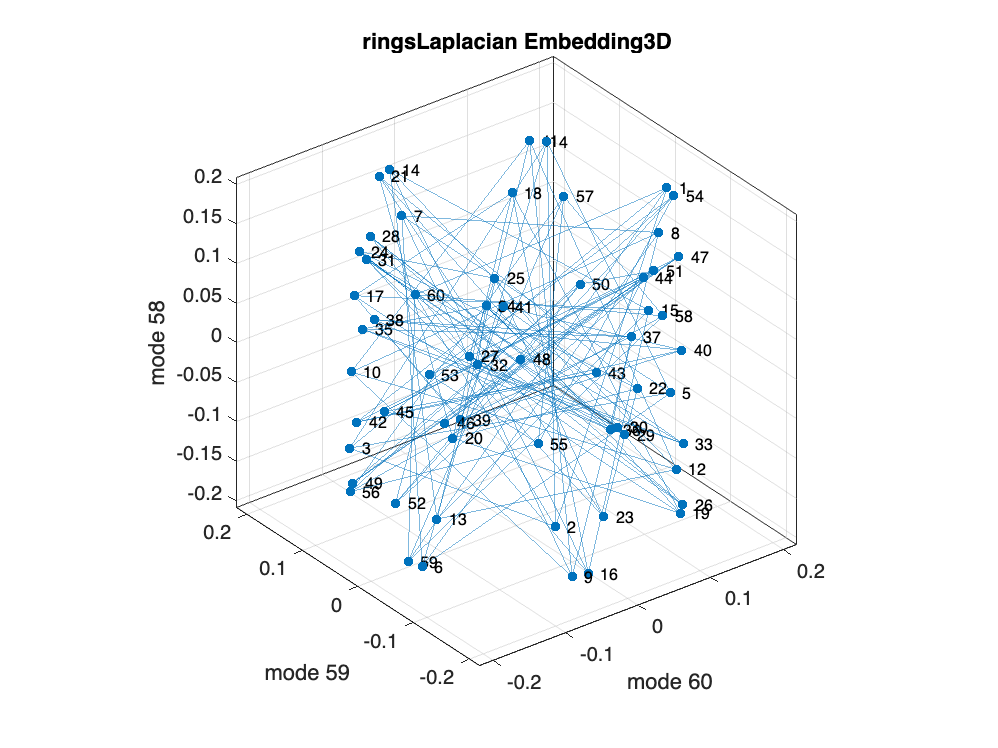



   demo_Laplacian_spectra end 



demo_Laplacian_spectra;

fiedler_vector = Leig.V(:, 2);  % Second smallest eigenvector

% Partition the graph using the Fiedler vector
partition1 = find(fiedler_vector > 0);   % Positive values in Fiedler vector
partition2 = find(fiedler_vector <= 0);  % Non-positive values in Fiedler vector


% Create graph object
G = graph(A);

disp('Plotting...');

Plotting...


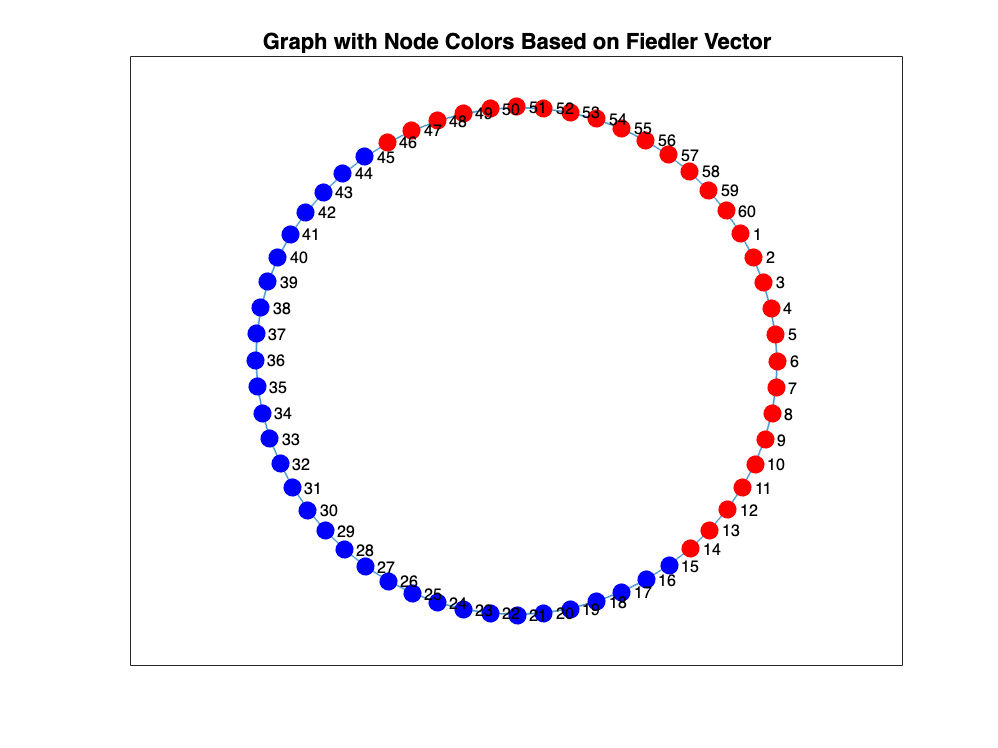

% Plot the graph without using NodeCData
figure
h = plot(G, 'MarkerSize', 8);
title('Graph Cut Using Fiedler Vector');
axis equal; box on;

% Highlight partition 1 (nodes with positive Fiedler vector values) in red
highlight(h, partition1, 'NodeColor', 'r');

% Highlight partition 2 (nodes with non-positive Fiedler vector values) in blue
highlight(h, partition2, 'NodeColor', 'b');
title('Graph with Node Colors Based on Fiedler Vector');
axis equal; box on;

% Load Facebook network edge list and adjust the indices to 1-based
edges = readmatrix('data/facebook/facebook_combined.txt', 'FileType', 'text');
edges = edges + 1;  % Convert to 1-based indexing

% Create graph from edges
G = graph(edges(:, 1), edges(:, 2));
num_nodes = numnodes(G);
num_edges = numedges(G);

% Print graph properties
fprintf('--- Facebook Network ---\n');

--- Facebook Network ---


fprintf('n (Number of nodes): %d\n', num_nodes);

n (Number of nodes): 4039


fprintf('m (Number of edges): %d\n', num_edges);

m (Number of edges): 88234


fprintf('\n');

% Convert graph to adjacency matrix
A = adjacency(G);

% Perform Laplacian spectral analysis and spectral embedding
fprintf('Running Laplacian Spectral Analysis...\n');

Running Laplacian Spectral Analysis...



   demo_Laplacian_spectra_realworld begin 

Using sparse solver with sigma = 0.0001 for better stability...


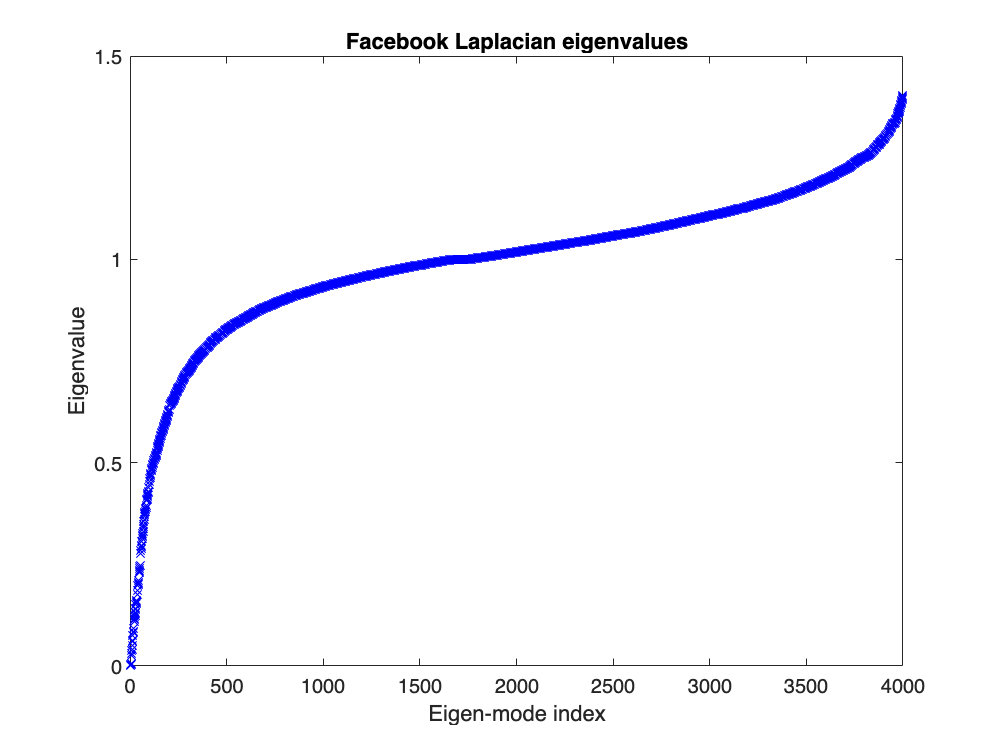

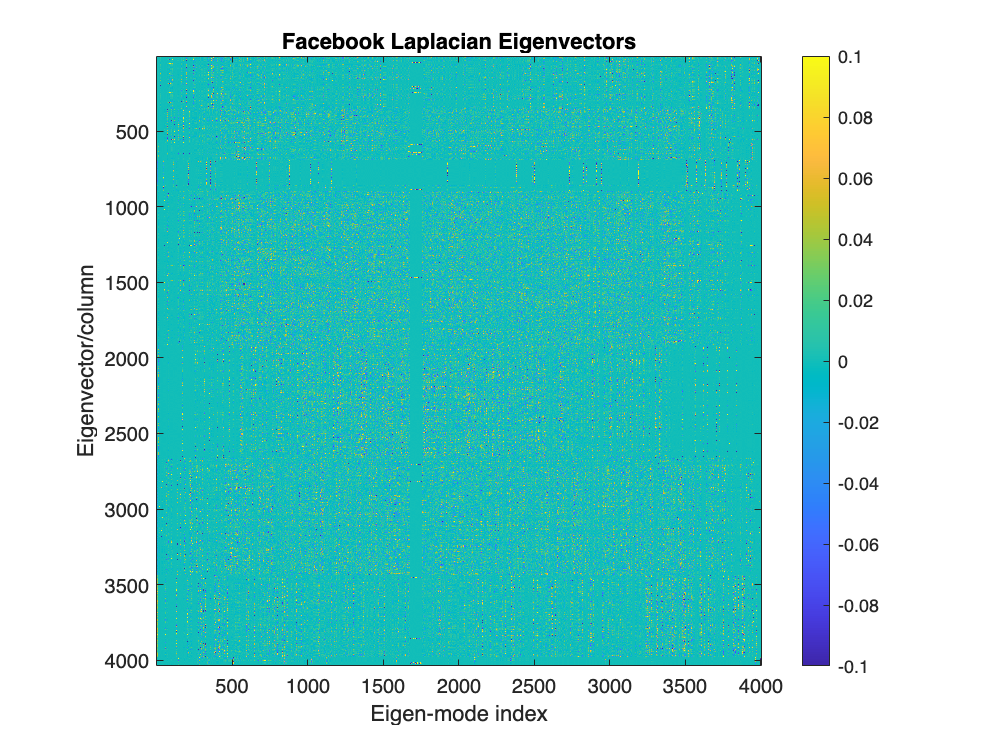

2D vertex embedding with low-energy modes...


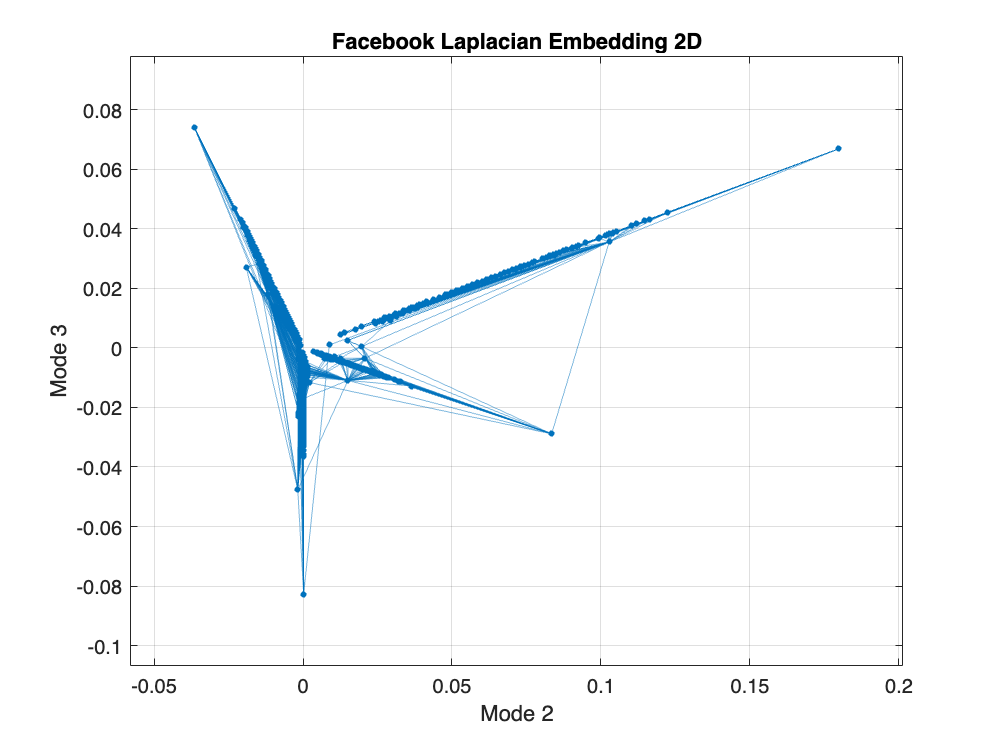

3D vertex embedding with low-energy modes...


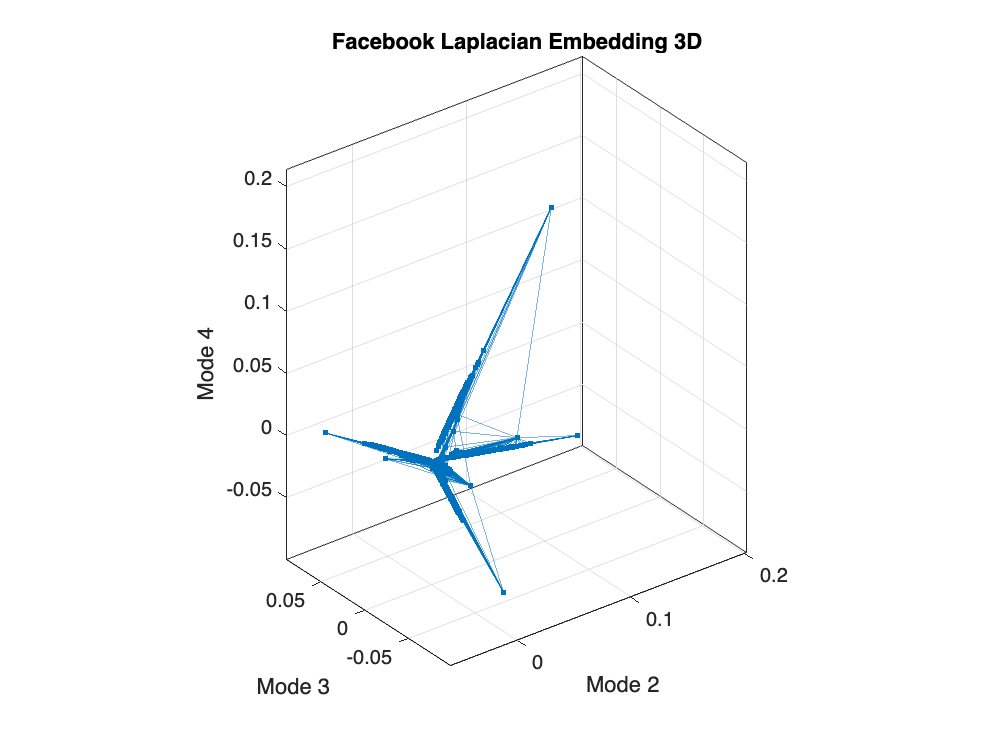

3D vertex embedding with high-energy modes...


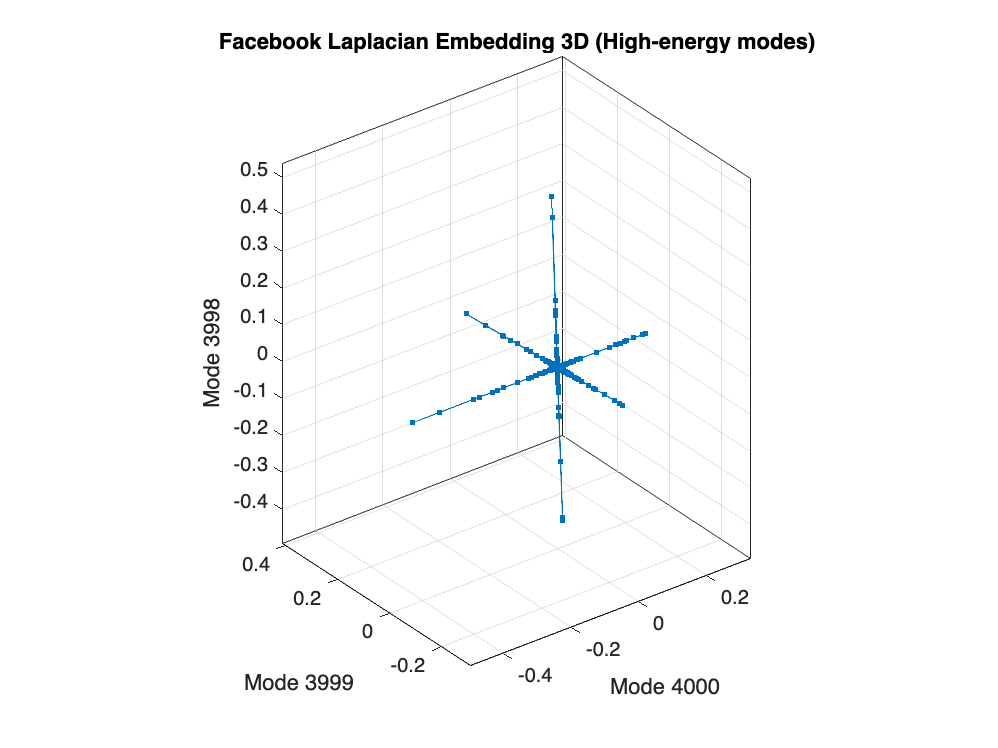



   demo_Laplacian_spectra_realworld end 



% Call the modified Laplacian spectral analysis function
% This will compute and return the eigenvalues and eigenvectors in 'Leig' structure
Leig = demo_Laplacian_spectra_realworld(A, 'Facebook', 1);


% Access the Fiedler vector (second smallest eigenvector) from Leig structure
fiedler_vector = Leig.V(:, 2);  % Second smallest eigenvector (Fiedler vector)

% Partition the graph using the Fiedler vector
partition1 = find(fiedler_vector > 0);   % Positive values in Fiedler vector
partition2 = find(fiedler_vector <= 0);  % Non-positive values in Fiedler vector

% Create graph object
fprintf('Creating graph partition plot...\n');

Creating graph partition plot...


G = graph(A);  % Re-create the graph from adjacency matrix if needed

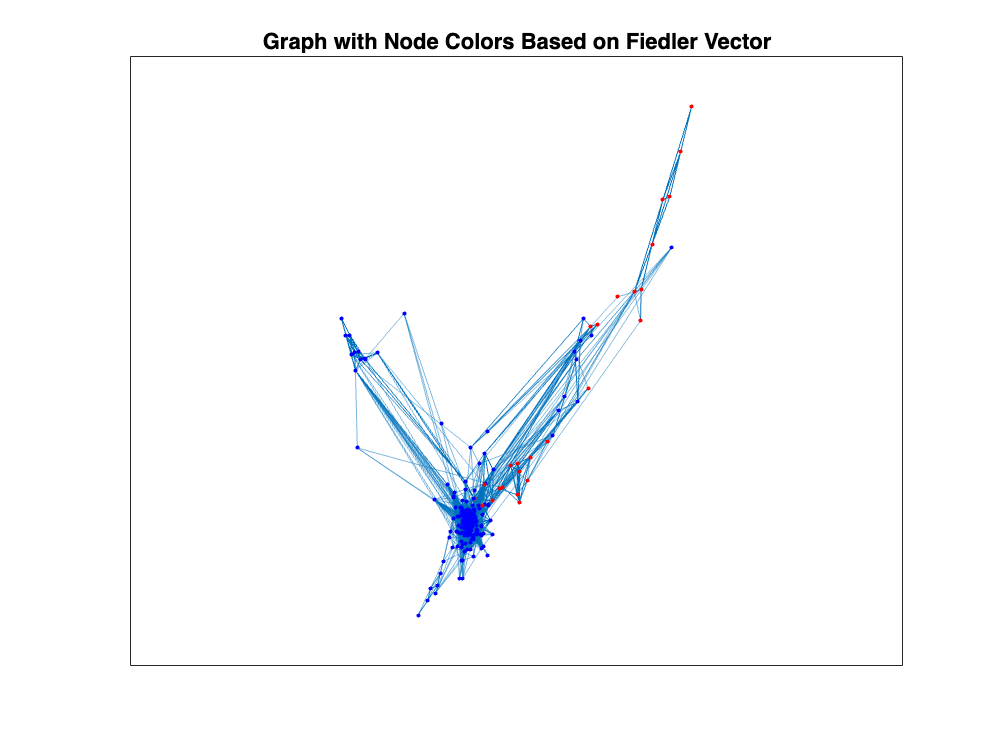


% Plot the graph with partitions based on the Fiedler vector
figure
h = plot(G, 'MarkerSize', 1);
title('Graph Cut Using Fiedler Vector');
axis equal; box on;

% Highlight partition 1 (nodes with positive Fiedler vector values) in red
highlight(h, partition1, 'NodeColor', 'r');

% Highlight partition 2 (nodes with non-positive Fiedler vector values) in blue
highlight(h, partition2, 'NodeColor', 'b');
title('Graph with Node Colors Based on Fiedler Vector');
axis equal; box on;


disp('Graph partitioning complete.');

Graph partitioning complete.
